## Sound analysis lecture

clear
[signal,Fs] = audioread('AudioTest\130BPM_PIANO_multiNote.wav');


signal = signal(:,1) % signal = toutes les lignes de la première colonne

signal =     0.0003
    0.0007
    0.0005
    0.0001
   -0.0001
    0.0002
    0.0012
    0.0025
    0.0031
    0.0024


FFTSize = 4096;
hopsize = 200; %changer de nom overlapp, overlap = nombre de samples commun
overlapp = FFTSize -hopsize;

[FFTVector,frequencyBand,newTime] = spectrogram (signal,FFTSize,overlapp,FFTSize-1,Fs,'yaxis')

FFTVector = 	1.0e+02 *

  -0.0021 + 0.0000i   0.0017 + 0.0000i   0.0008 + 0.0000i  -0.0004 + 0.0000i   0.0028 + 0.0000i   0.0007 + 0.0000i   0.0023 + 0.0000i   0.0031 + 0.0000i   0.0001 + 0.0000i   0.0043 + 0.0000i   0.0017 + 0.0000i  -0.0000 + 0.0000i   0.0036 + 0.0000i  -0.0019 + 0.0000i   0.0008 + 0.0000i   0.0015 + 0.0000i  -0.0031 + 0.0000i   0.0010 + 0.0000i  -0.0007 + 0.0000i  -0.0022 + 0.0000i   0.0012 + 0.0000i  -0.0014 + 0.0000i  -0.0008 + 0.0000i   0.0020 + 0.0000i  -0.0018 + 0.0000i   0.0017 + 0.0000i   0.0012 + 0.0000i  -0.0010 + 0.0000i   0.0026 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i   0.0015 + 0.0000i  -0.0013 + 0.0000i  -0.0004 + 0.0000i  -0.0011 + 0.0000i  -0.0041 + 0.0000i   0.0004 + 0.0000i  -0.0046 + 0.0000i  -0.0047 + 0.0000i  -0.0003 + 0.0000i  -0.0064 + 0.0000i  -0.0039 + 0.0000i  -0.0014 + 0.0000i  -0.0066 + 0.0000i  -0.0023 + 0.0000i  -0.0024 + 0.0000i  -0.0046 + 0.0000i  -0.0006 + 0.0000i  -0.0010 + 0.0000i  -0.0024 + 0.0000i
   0.0009 + 0.0010i   0.0

frequencyBand = 	1.0e+04 *

         0
    0.0011
    0.0022
    0.0032
    0.0043
    0.0054
    0.0065
    0.0075
    0.0086
    0.0097


newTime =     0.0464    0.0510    0.0555    0.0600    0.0646    0.0691    0.0737    0.0782    0.0827    0.0873    0.0918    0.0963    0.1009    0.1054    0.1099    0.1145    0.1190    0.1235    0.1281    0.1326    0.1371    0.1417    0.1462    0.1507    0.1553    0.1598    0.1644    0.1689    0.1734    0.1780    0.1825    0.1870    0.1916    0.1961    0.2006    0.2052    0.2097    0.2142    0.2188    0.2233    0.2278    0.2324    0.2369    0.2415    0.2460    0.2505    0.2551    0.2596    0.2641    0.2687


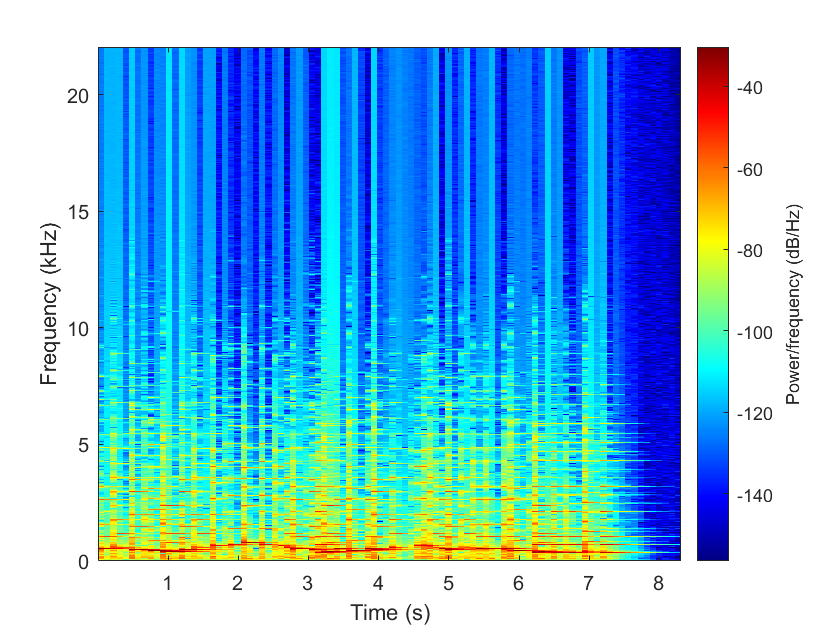

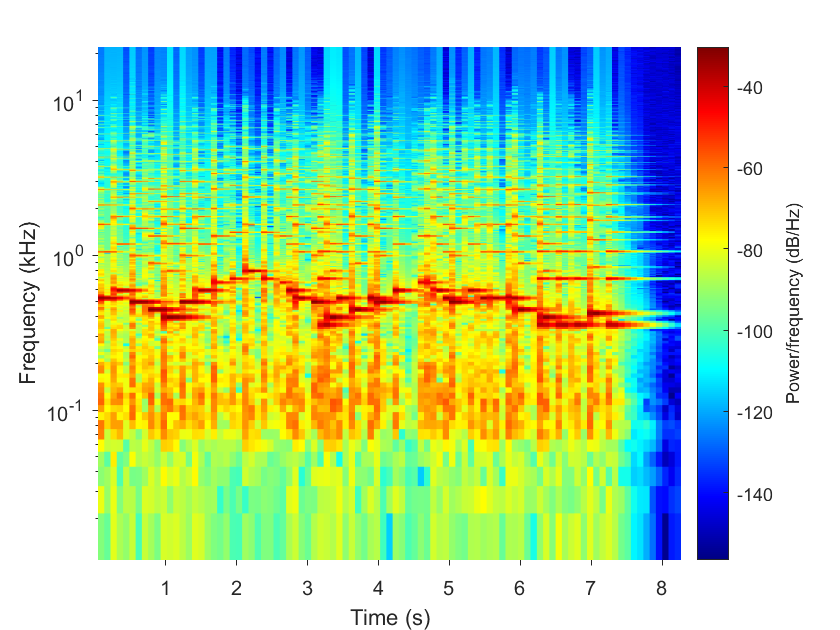

spectrogram (signal,FFTSize,hopsize,FFTSize,Fs,'yaxis');
colormap jet
set(gca, 'YScale', 'log')

N = length(signal)

N = 369974

time = [0:N-1]/Fs

time =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


%le nombre de FFT a effectuer pour couvrir tout le signal
numberFFT  = size(FFTVector,2)

numberFFT = 1830



unwrappedPhase = zeros(FFTSize/2,numberFFT)

unwrappedPhase =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

deltaPhi = zeros(FFTSize/2,numberFFT)

deltaPhi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

%enveloppe folower
EnveloppeFolow = zeros(numberFFT)

EnveloppeFolow =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

%local energieFolower
LocalEnergieFolow = zeros(numberFFT,1)

LocalEnergieFolow =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%vector pour garder l'énergie de la FFT - version sans pondération
%fréquentielle
FFT_SimpleEnergie = zeros(numberFFT,1)

FFT_SimpleEnergie =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%vector pour garder l'énergie de la FFT - version sans pondération
%fréquentielle
FFT_HFC = zeros(numberFFT,1)

FFT_HFC =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



%vector pour enregistrer les différences de spectres entre deux FFT
FFT_spectralDiff = zeros(numberFFT,1)

FFT_spectralDiff =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



sumDeltaPhi = zeros(numberFFT,1)

sumDeltaPhi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%new time est la nouvelle Fs, on sample moins vite, on divise Fs par
%l'overlapp




%indexFFT parcours le nombre de FFT a effectuer de 0 à numberFFT-1
%indexPosition parcours la FFT de 1 à la taille de la FFT

for indexFFT = 0:1:numberFFT-1 

    %the value contient la portion de signal a traiter
    %TODO : fonction fenetrage
    theValue = signal(1+indexFFT*hopsize:FFTSize+indexFFT*hopsize);
    
    
    unwrappedPhase(:,indexFFT+1) = angle(FFTVector(:,indexFFT+1));
    
    EnveloppeFolow(indexFFT+1) = 1/FFTSize * sum(abs(theValue));
    LocalEnergieFolow(indexFFT+1) = 1/FFTSize *sum(theValue.^2);
    %la boucle parcours tous les élèments de la FFT
    for indexPosition = 1:1:FFTSize/2         
        %pour chaque FFT, on calcule son énergie et on la met dans un tableau
        FFT_SimpleEnergie(indexFFT+1) = FFT_SimpleEnergie(indexFFT+1,1) + (abs(FFTVector(indexPosition,indexFFT+1)))^2;
        
        FFT_HFC(indexFFT+1,1) = FFT_HFC(indexFFT+1,1) + indexPosition*(abs(FFTVector(indexPosition,indexFFT+1)))^2;
        
        % si on a deja effectuer une FFT
        if(indexFFT > 0)
            %algorithme spectral difference
            
            %difference entre deux bins consecutives
            localSpectralDiff = abs(FFTVector(indexPosition,indexFFT+1)) - abs(FFTVector(indexPosition,indexFFT));
            %on ne garde que les incréments d'énérgie 
            localSpectralDiff = (localSpectralDiff + abs(localSpectralDiff))/2;
            FFT_spectralDiff(indexFFT+1,1) = FFT_spectralDiff(indexFFT+1,1) + localSpectralDiff;
        end
        if(indexFFT>1)
            deltaPhi(indexPosition,indexFFT+1) = unwrappedPhase(indexPosition,indexFFT+1)-2*unwrappedPhase(indexPosition,indexFFT)+unwrappedPhase(indexPosition,indexFFT-1);
        end
    end
    FFT_SimpleEnergie(indexFFT+1,1) = 1/FFTSize *FFT_SimpleEnergie(indexFFT+1,1);
    FFT_HFC(indexFFT+1,1) = 1/FFTSize *FFT_HFC(indexFFT+1,1);
    
    sumDeltaPhi(indexFFT+1,1) = 1/FFTSize* sum(abs(deltaPhi(:,indexFFT+1)));
    
end

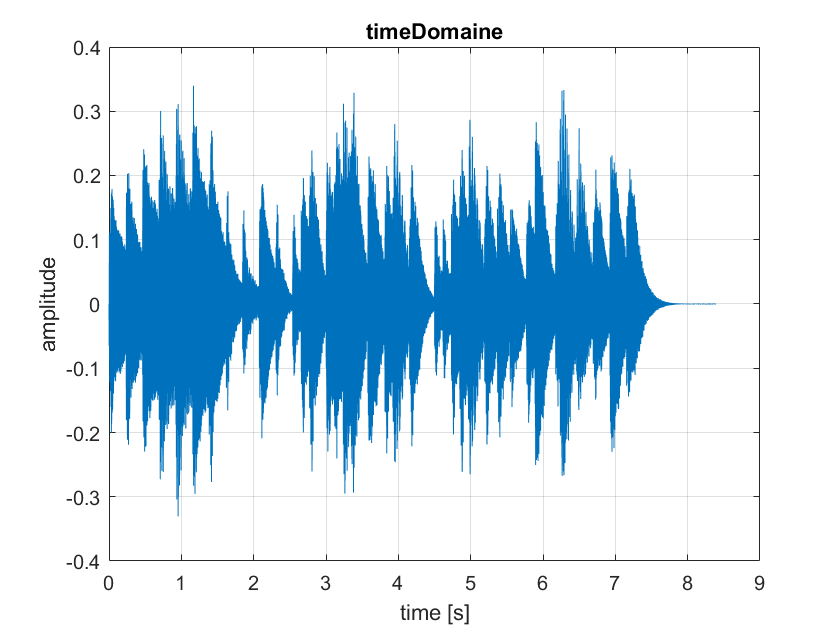

%time domaine signal
plot(time,signal)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("timeDomaine")

%stat info
maxValue = max(signal)

maxValue = 0.3398

minValue = min(signal)

minValue = -0.3306

meanValue = mean(signal)

meanValue = -9.4152e-06

stdValue = std(signal) %standart deviation

stdValue = 0.0774

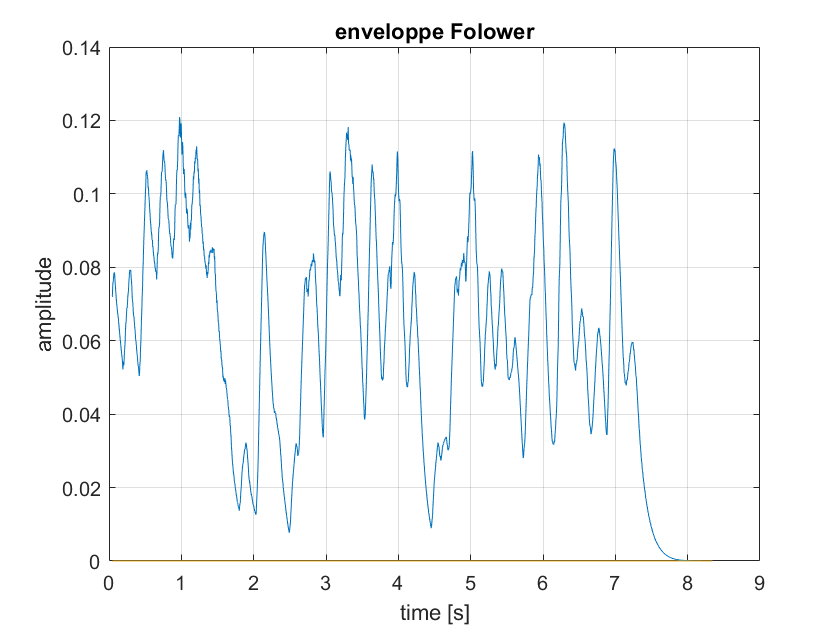

plot(newTime ,EnveloppeFolow)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("enveloppe Folower")

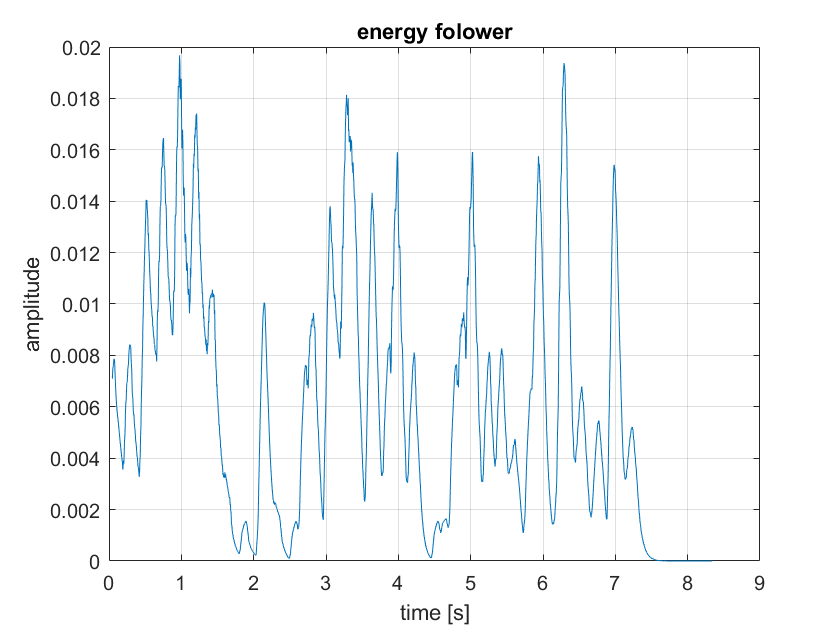



plot(newTime,LocalEnergieFolow)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("energy folower")

LocalEnergieFolow_maxValue = max(LocalEnergieFolow)

LocalEnergieFolow_maxValue = 0.0197

LocalEnergieFolow_minValue = min(LocalEnergieFolow)

LocalEnergieFolow_minValue = 1.8167e-10

LocalEnergieFolow_meanValue = mean(LocalEnergieFolow)

LocalEnergieFolow_meanValue = 0.0060

LocalEnergieFolow_stdValue = std(LocalEnergieFolow) %standart deviation

LocalEnergieFolow_stdValue = 0.0049

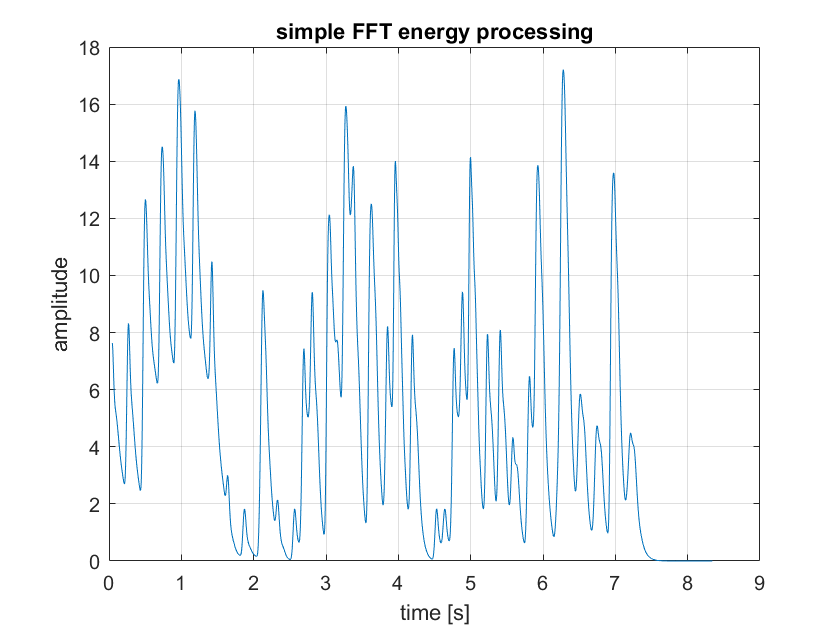

plot(newTime,FFT_SimpleEnergie)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("simple FFT energy processing")

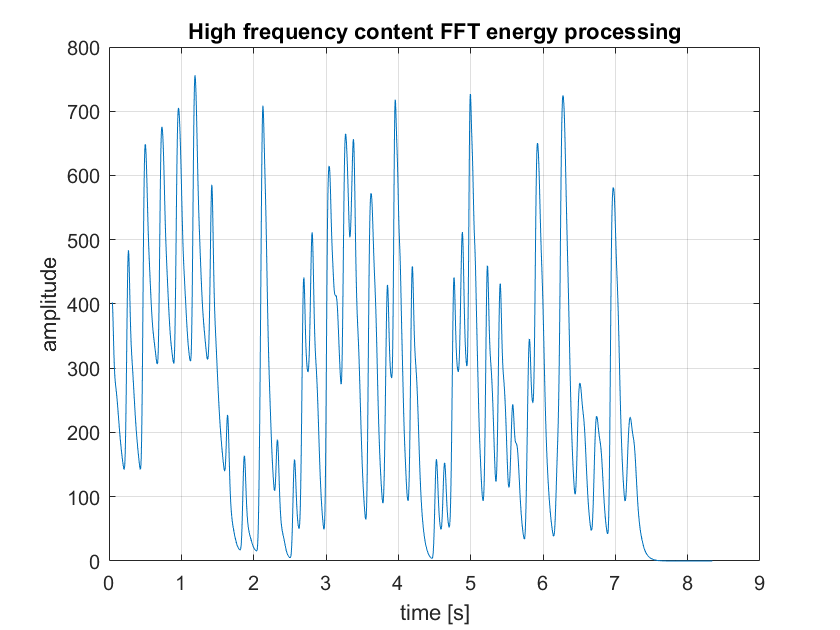

plot(newTime,FFT_HFC)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("High frequency content FFT energy processing")

%stat info
FFT_HFC_maxValue = max(FFT_HFC)

FFT_HFC_maxValue = 755.8967

FFT_HFC_minValue = min(FFT_HFC)

FFT_HFC_minValue = 2.4560e-05

FFT_HFC_meanValue = mean(FFT_HFC)

FFT_HFC_meanValue = 248.5604

FFT_HFC_stdValue = std(FFT_HFC) %standart deviation

FFT_HFC_stdValue = 199.2066

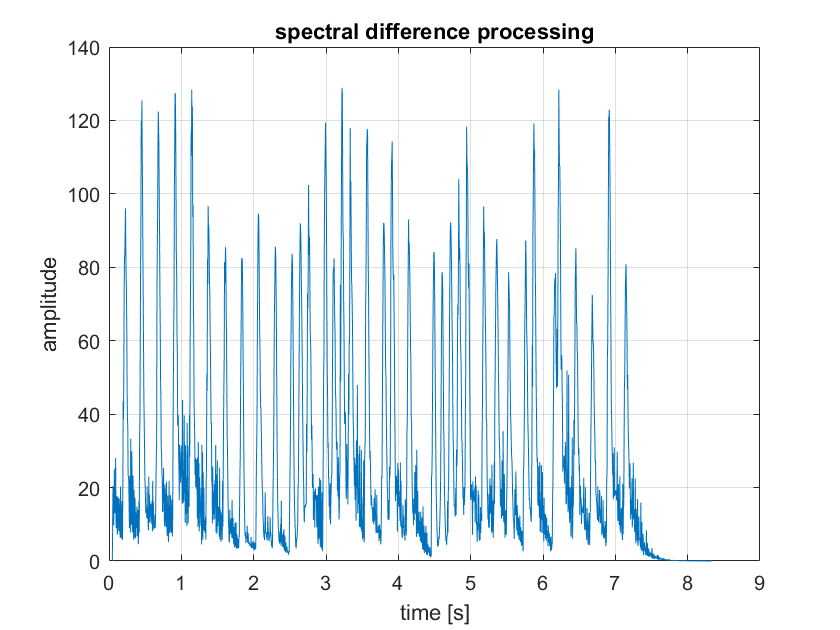

plot(newTime,FFT_spectralDiff)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("spectral difference processing")

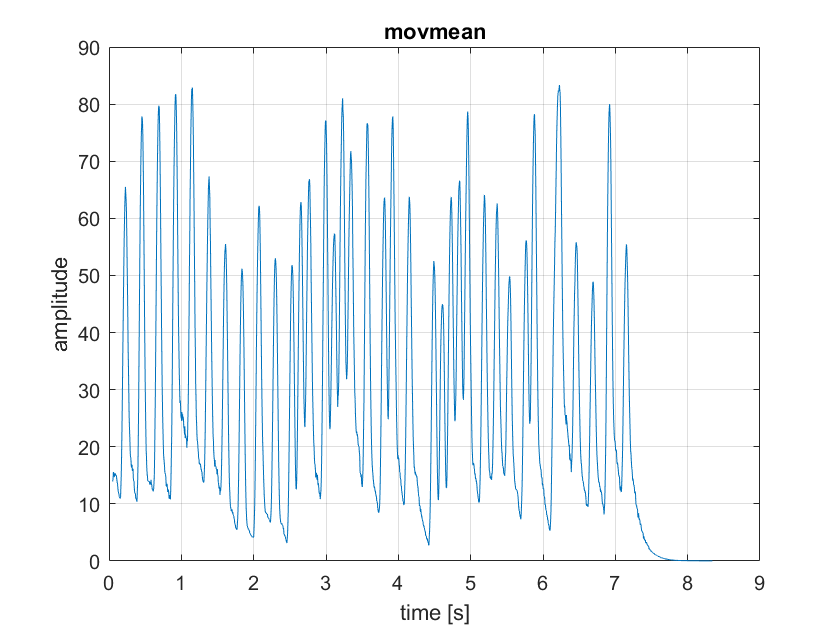


M = movmean(FFT_spectralDiff,15);
plot(newTime,M)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("movmean")

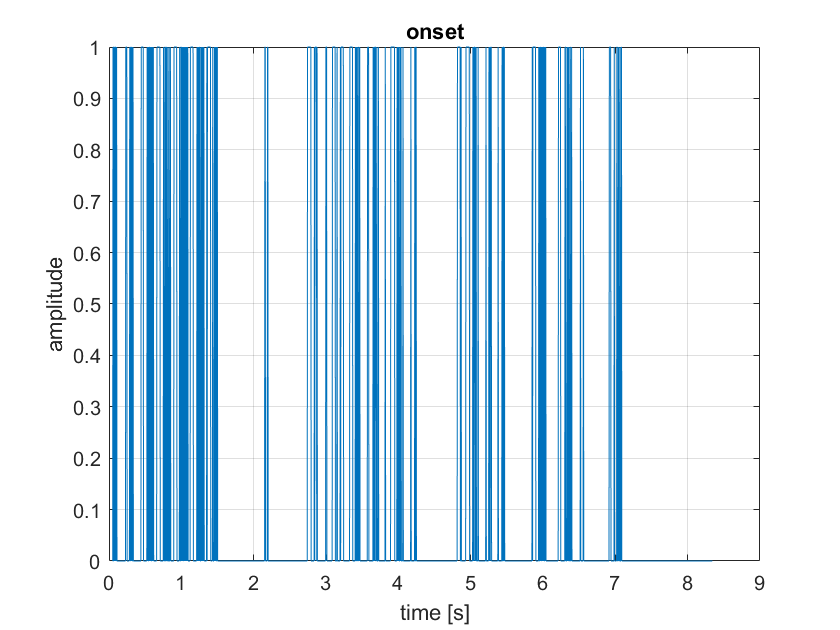

onset = zeros(size(M));
onsetTime = zeros(size(M));

for indexTime = 1 : size(M)
    if(FFT_spectralDiff(indexTime) >= M(indexTime))
        if(LocalEnergieFolow(indexTime)> LocalEnergieFolow_meanValue)
            onset(indexTime) = 1;
        end
    else
        onset(indexTime) = 0;
    end
    if(onset(indexTime) == 1 && onset(indexTime-1) == 0)
        onsetTime(indexTime) =1;
    
    end
    
end
plot(newTime,onset)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("onset")

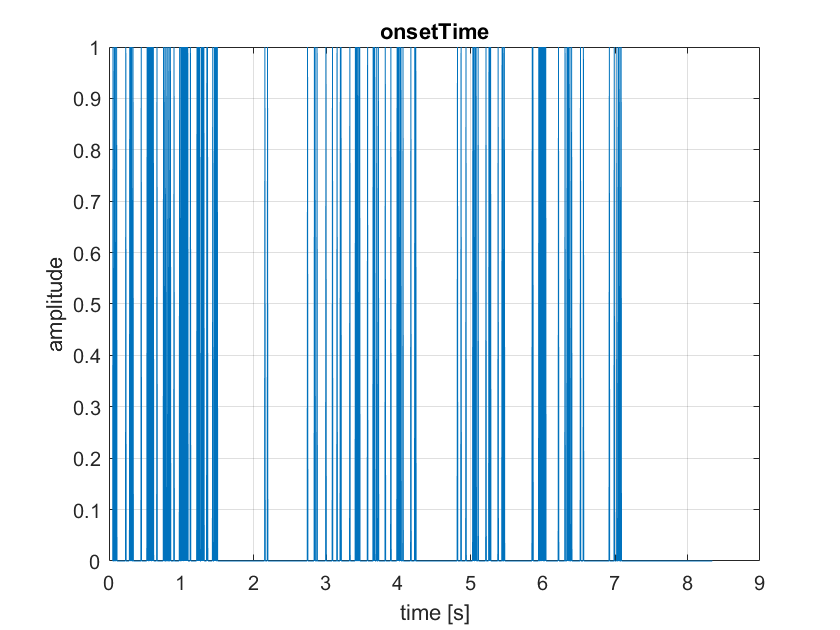

plot(newTime,onsetTime)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("onsetTime")

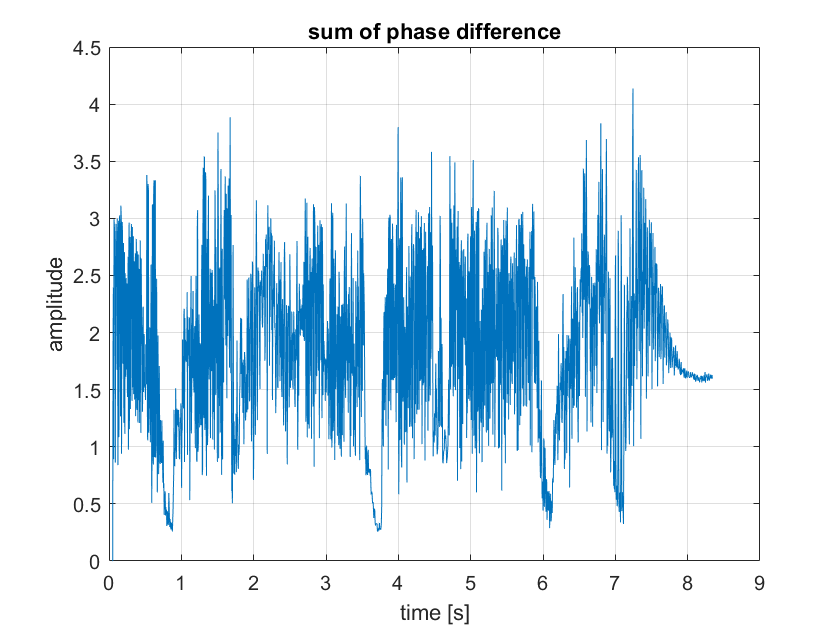

plot(newTime,sumDeltaPhi)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("sum of phase difference")

Computing miraudio related to AudioTest\130BPM_PIANO_multiNote.wav...
Computing mirsum related to AudioTest\130BPM_PIANO_multiNote.wav...
Computing mirspectrum related to AudioTest\130BPM_PIANO_multiNote.wav...
Computing mirenvelope related to AudioTest\130BPM_PIANO_multiNote.wav...
Computing mironsets related to AudioTest\130BPM_PIANO_multiNote.wav...
Computing mirsum related to AudioTest\130BPM_PIANO_multiNote.wav...
Computing mirenvelope related to AudioTest\130BPM_PIANO_multiNote.wav...
Computing mirpeaks related to AudioTest\130BPM_PIANO_multiNote.wav...
Elapsed time is 4.912953 seconds.
 
test is the Onset curve (Envelope) related to AudioTest\130BPM_PIANO_multiNote.wav, of sampling rate 100 Hz.


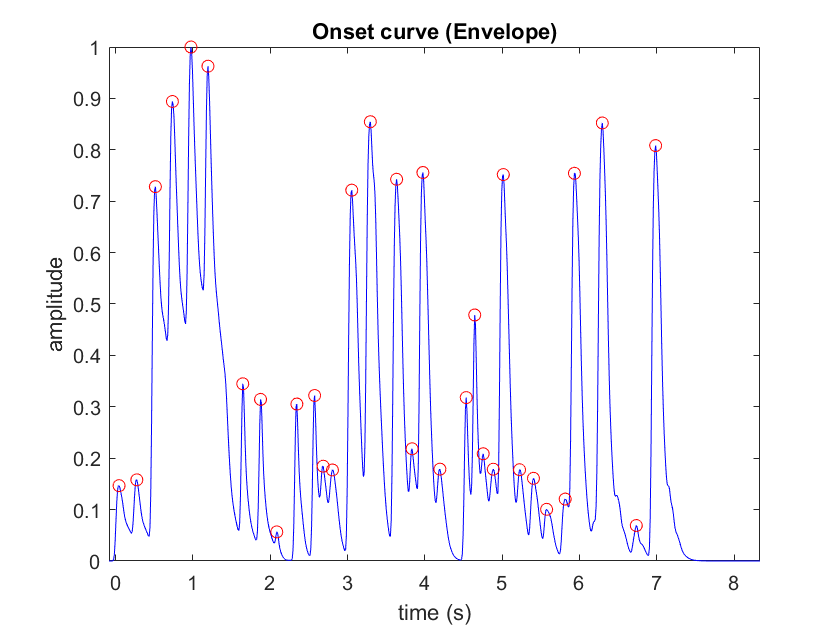

Its content is displayed in Figure 10.
 


test = mirevents( 'AudioTest\130BPM_PIANO_multiNote.wav','Detect')

mirgetdata(test)

ans =     0.0411
    0.2699
    0.5124
    0.7358
    0.9750
    1.1942
    1.6482
    1.8788
    2.0878
    2.3403
